# MAE 4733 - Automatic Control Systems: Final Project

Diego Colón

12-9-2020

clear all

## Final Project brief

For this project we are to design controllers for a simplified planar bicopter with equations of motion


$$\begin{array}{l}
\ddot{h} \left(t\right)=-g+\frac{1}{M+2m}\cos \left(\theta \left(t\right)\right)F\left(t\right)\\
\ddot{z} \left(t\right)=-\frac{\mu }{M+2m}\dot{z} -\frac{1}{M+2m}\sin \left(\theta \left(t\right)\right)F\left(t\right)\\
\theta^¨ \left(t\right)=\frac{1}{2{\textrm{md}}^2 +J}\tau \left(t\right)
\end{array}$$


through the use of pole placement and loop shaping methods.

## Part 1 - Pole Placement

### 1.1 - State Space Model

The system dynamics provided above can be expressed in a state space form ($x=f\left(x,u\right),y=\phi \left(x,h\right)$) , with state $x={}{\left\lbrack \begin{array}{cccccc}
h & \dot{h}  & z & \dot{z}  & \theta  & \theta^˙ 
\end{array}\right\rbrack }^T$and input $u={}{\left\lbrack \begin{array}{cc}
F & \tau 
\end{array}\right\rbrack }^T$ as:


$$\dot{x} =f\left(x,u\right)=\left\lbrack \begin{array}{c}
\dot{h} \\
\frac{\textrm{Fcos}\left(\theta \right)}{M+2m}-g\\
\dot{z} \\
-\frac{\mu \dot{z} }{M+2m}-\frac{\textrm{Fsin}\left(\theta \right)}{M+2m}\\
\theta^˙ \\
\frac{\tau }{2{\textrm{md}}^2 +J}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
\frac{u_1 \cos \left(x_5 \right)}{M+2m}-g\\
x_4 \\
-\frac{\mu x_4 }{M+2m}-\frac{u_1 \sin \left(x_5 \right)}{M+2m}\\
x_6 \\
\frac{u_2 }{2{\textrm{md}}^2 +J}
\end{array}\right\rbrack$$



$$y=\phi \left(x,u\right)=\left\lbrack \begin{array}{c}
h\\
z\\
\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_3 \\
x_5 
\end{array}\right\rbrack$$


### 1.2 - Equilibium Trajectory

In order to create controllers, with the techniques learned in class, it is required to linearize the dynamics about an equilibrium trajectory. Equilibrium trajectories and its corresponding measurements are defined as:


$$\left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)\owns \dot{x} \left(t\right)=f\left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)=0\;\forall \;t\ge 0$$



$$y^{\ast } \left(t\right)=\phi \left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)$$


%% Create all the system variables
syms s 
syms h h_dot h_ddot z z_dot z_ddot theta theta_dot theta_ddot 
syms g M m mu d J
syms F tau

%% Create symbols and values array for substitution
k = [g; M; m;  mu; d; J];
k_val = [9.81; 1; 0.25;  0.1; 0.3; 0.0042];

%% Write the planar bicopter dynamics Dynamics
h_ddot = -g +(cos(theta)*F)/(M+2*m);
z_ddot = -(mu*z_dot)/(M+2*m) - (sin(theta)*F)/(M+2*m);
theta_ddot = tau/(2*m*d^2 + J);

%% Create x, u, f(x,u) and h(x,u)
x = [h; h_dot; z; z_dot; theta; theta_dot]

$$x = \left(\begin{array}{c} h\\ \dot{h}\\ z\\ \dot{z}\\ \theta \\ \dot{\theta } \end{array}\right)$$

u = [F;tau]

$$u = \left(\begin{array}{c} F\\ \tau \end{array}\right)$$

process = [h_dot; h_ddot; z_dot; z_ddot; theta_dot; theta_ddot]

$$process = \left(\begin{array}{c} \dot{h}\\ \frac{F\,\cos\left(\theta \right)}{M+2\,m}-g\\ \dot{z}\\ -\frac{\mu \,\dot{z}}{M+2\,m}-\frac{F\,\sin\left(\theta \right)}{M+2\,m}\\ \dot{\theta }\\ \frac{\tau }{2\,m\,d^{2}+J} \end{array}\right)$$

meas = [h; z; theta]

$$meas = \left(\begin{array}{c} h\\ z\\ \theta \end{array}\right)$$

%% Solve for the equilibrium trajectory
S = solve(process,[x;u]);
x_star = [S.h+10;S.h_dot;S.z;S.z_dot;S.theta;S.theta_dot]

$$x\_star = \left(\begin{array}{c} 10\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

u_star = [S.F;S.tau]

$$u\_star = \left(\begin{array}{c} g\,\left(M+2\,m\right)\\ 0 \end{array}\right)$$

y_star= [S.h+10;S.z;S.theta]

$$y\_star = \left(\begin{array}{c} 10\\ 0\\ 0 \end{array}\right)$$

### 1.3 - Linearize Dynamics

Once a equilibrium trajectory has been found, the dynamics can be linearized about them and written in the matrix form


$$\begin{array}{l}
{}{\dot{x} }_{\delta }=A{}x_{\delta }+B{}u_{\delta }\\
{}y_{\delta }=C{}x_{\delta }+D{}u_{\delta }
\end{array}$$


A = simplify(subs(jacobian(process,x),[x;u],[x_star;u_star]))

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & -\frac{\mu }{M+2\,m} & -g & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B = simplify(subs(jacobian(process,u),[x;u],[x_star;u_star]))

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{M+2\,m} & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & \frac{1}{2\,m\,d^{2}+J} \end{array}\right)$$

C = simplify(subs(jacobian(meas,x),[x;u],[x_star;u_star]))

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

D = simplify(subs(jacobian(meas,u),[x;u],[x_star;u_star]))

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

x_star = subs(x_star,k,k_val);
u_star = subs(u_star,k,k_val);

### 1.4 - MIMO TF

Since the bicopter is a multi-input multi-output system, the dynamics can be written as a MIMO tranfer function. In this case that transfer function is of the form


$$\left\lbrack \begin{array}{c}
H\left(s\right)\\
Z\left(s\right)\\
\Theta \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{}G_{\textrm{HF}}\left(s\right) & {}G_{FT}\left(s\right)\\
{}G_{\textrm{ZF}}\left(s\right) & {}G_{ZT}\left(s\right)\\
{}G_{\Theta F}\left(s\right) & {}G_{\Theta T}\left(s\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F\left(s\right)\\
T\left(s\right)
\end{array}\right\rbrack$$


G_XU = collect(simplify(C*inv(s*eye(size(A, 1)) - A)*B + D),s)

$$G\_XU = \left(\begin{array}{cc} \frac{1}{\left(M+2\,m\right)\,s^{2}} & 0\\ 0 & \frac{-M\,g-2\,g\,m}{\left(4\,d^{2}\,m^{2}+2\,M\,d^{2}\,m+2\,J\,m+J\,M\right)\,s^{4}+\left(2\,m\,\mu \,d^{2}+J\,\mu \right)\,s^{3}}\\ 0 & \frac{1}{\left(2\,m\,d^{2}+J\right)\,s^{2}} \end{array}\right)$$

### 1.5 - Relevant Transfer Functions

Taking the nonzero transfer functions out of the MIMO transfer function

G_HF = collect(simplify(subs(G_XU(1,1),k,k_val)),s)

$$G\_HF = \frac{2}{3\,s^{2}}$$

G_HF_poles = poles(collect(simplify(subs(G_XU(1,1),k,k_val)),s))

$$G\_HF\_poles = 0$$


G_ZT = collect(simplify(subs(G_XU(2,2),k,k_val)),s)

$$G\_ZT = -\frac{122625}{615\,s^{4}+41\,s^{3}}$$

G_ZT_poles = poles(collect(simplify(subs(G_XU(2,2),k,k_val)),s))

$$G\_ZT\_poles = \left(\begin{array}{c} 0\\ -\frac{1}{15} \end{array}\right)$$


G_ThetaT = collect(simplify(subs(G_XU(3,2),k,k_val)),s)

$$G\_ThetaT = \frac{2500}{123\,s^{2}}$$

G_ThetaT_poles = poles(collect(simplify(subs(G_XU(3,2),k,k_val)),s))

$$G\_ThetaT\_poles = 0$$

### 1.6 - Missing TF

Given the nature of the linearized dynamics and the controller architecture we would like to implement, it is required to know the relationship between $Z$ and $\Theta$. 


$$\frac{Z\left(s\right)}{\Theta \left(s\right)}=\frac{Z\left(s\right)}{T\left(s\right)}\frac{T\left(s\right)}{\Theta \left(s\right)}=\frac{G_{ZT} \left(s\right)}{G_{\Theta T} \left(s\right)}=G_{Z\Theta } \left(s\right)$$


G_ZTheta = collect(simplify(G_ZT/G_ThetaT),s)

$$G\_ZTheta = -\frac{2943}{300\,s^{2}+20\,s}$$

G_ZTheta_poles = poles(collect(simplify(subs(G_ZTheta,k,k_val)),s))

$$G\_ZTheta\_poles = \left(\begin{array}{c} -\frac{1}{15}\\ 0 \end{array}\right)$$

### 1.7 - Controller Architecture

Since the lateral and longitudinal dynamics of the linearized simplified planar bicopter are decoupled, a different feedback control loop will be used for each of the dynamics. In the case of the longitudinal dynamics a single loop is all that is needed. In the case of the lateral dynamics an inner-outer loop structure is required because the lateral position is coupled with the roll angle of the planar bicopter. The block diagram below shows the structure of the linearized controllers.

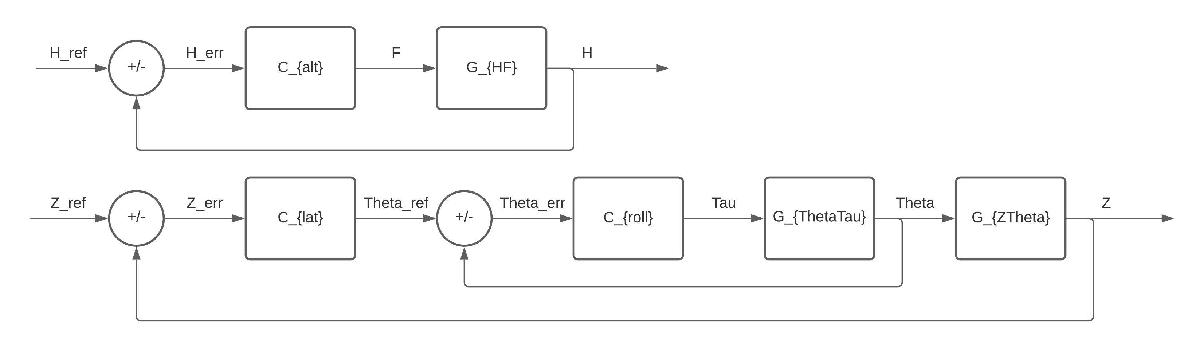

### 1.8 - Altitude Controller Design (Pole Placement)

For the longitudinal dynamics the time domain specifications are:

- 
$$T_r \approx 2\;\left\lbrack s\right\rbrack$$


- 
$$\zeta \approx 0\ldotp 707$$


Given that $G_{\textrm{HF}} \left(s\right)$has two poles at $s=0$, a PD controller is an appropiate choice

syms K_p K_d K_i
Cp1 = K_p + K_d * s;
CL1 = collect(simplify((G_HF*Cp1)/(1 + G_HF*Cp1)),s)

$$CL1 = \frac{\left(2\,K_{d}\right)\,s+2\,K_{p}}{3\,s^{2}+\left(2\,K_{d}\right)\,s+2\,K_{p}}$$

From the closed loop transfer function and the Routh–Hurwitz stability criteria, constraints on Kd and Kp can be found to be:

- 
$$K_p ,K_d >0$$


Applying coefficent matching between a desired second order system and the closed loop transfer function, equations for $K_p$ and $K_d$ can be written in terms of $T_r$ and $\zeta$

- 
$$\omega_n \approx \frac{2\ldotp 16\zeta +0\ldotp 6}{T_r }$$


- 
$$K_p =\frac{3}{2}\omega_n^2$$


- 
$$K_d =3\zeta \omega_n$$


[Num,Den] = numden(G_HF);
G_HF= tf(sym2poly(Num),sym2poly(Den));

t_r = 2;
zeta = 0.707;

omega_n = (2.16*zeta+0.6)/t_r;
Kp_alt = (3/2)*omega_n^2;
Kd_alt = 3*zeta*omega_n;
C_alt = tf([Kd_alt,Kp_alt,0],[1,0])

C_alt =
 
  2.256 s^2 + 1.697 s
  -------------------
           s
 
Continuous-time transfer function.



CL_alt = minreal(feedback(C_alt*G_HF,1))

CL_alt =
 
     1.504 s + 1.131
  ---------------------
  s^2 + 1.504 s + 1.131
 
Continuous-time transfer function.



stepinfo(CL_alt)

ans = struct with fields:
        RiseTime: 0.7956
    SettlingTime: 4.6010
     SettlingMin: 0.9331
     SettlingMax: 1.2079
       Overshoot: 20.7910
      Undershoot: 0
            Peak: 1.2079
        PeakTime: 2.0823


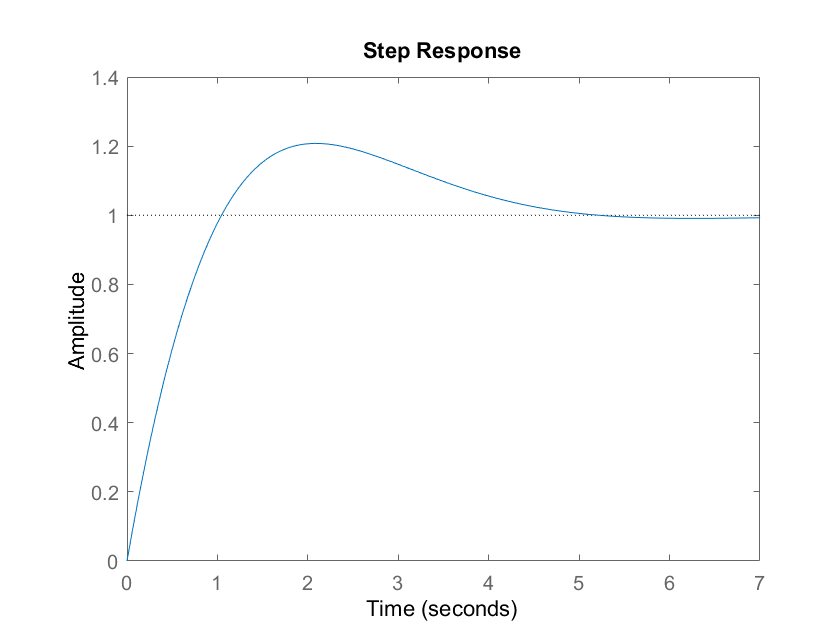

step(CL_alt)

isstable(CL_alt)

ans = logical
   1


Although the closed loop transfer function is stable, it does not meet the system specifications. This means that the choice of $\omega_n$ and $\zeta$have to be modified. With the knowledge that as $\omega_n \to \infty ,T_r \to 0$ and that $K_p ,K_d >0\;\forall \;\omega_n ,\zeta >0$, choices of $\omega_n$ were taken to meet the design specifications. The final design is as follows.

zeta = 0.8;
omega_n = 0.4;
Kp_alt = (3/2)*omega_n^2;
Kd_alt = (3/2)*(2*zeta*omega_n);
C_alt = tf([Kd_alt,Kp_alt,0],[1,0])

C_alt =
 
  0.96 s^2 + 0.24 s
  -----------------
          s
 
Continuous-time transfer function.



CL_alt = minreal(feedback(C_alt*G_HF,1))

CL_alt =
 
     0.64 s + 0.16
  -------------------
  s^2 + 0.64 s + 0.16
 
Continuous-time transfer function.



stepinfo(CL_alt)

ans = struct with fields:
        RiseTime: 2.0171
    SettlingTime: 12.6344
     SettlingMin: 0.9276
     SettlingMax: 1.1798
       Overshoot: 17.9763
      Undershoot: 0
            Peak: 1.1798
        PeakTime: 5.3247


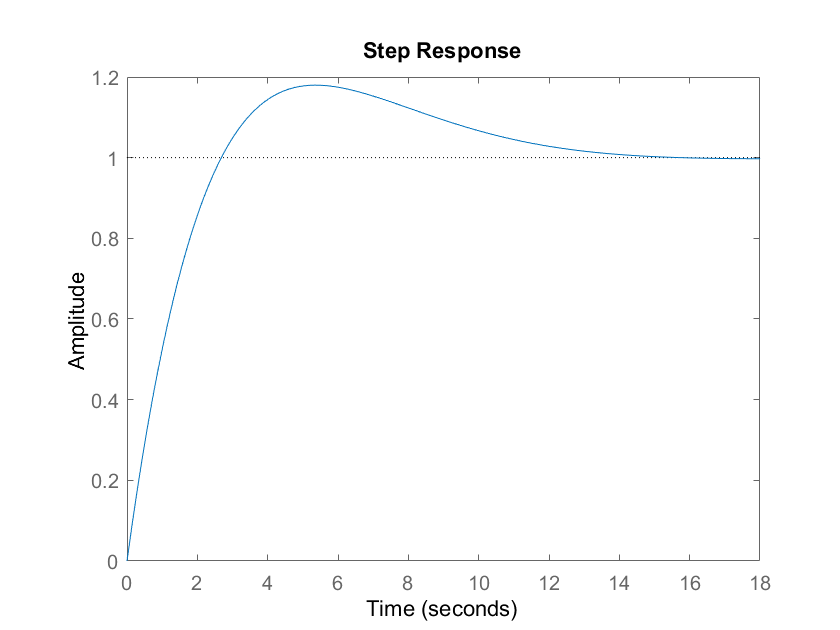

step(CL_alt)

isstable(CL_alt)

ans = logical
   1


### 1.9.1 - Inner Loop Controller Design (Pole Placement)

For the inner loop controller (roll controller), the time domain specifications go as follows

- $T_r \le 0\ldotp 3\;\left\lbrack s\right\rbrack$- The outer loop has been specified to be $3\;\left\lbrack s\right\rbrack$ and the inner loop should be 10 times faster than the outer loop.

- $T_s \le 1\;\left\lbrack s\right\rbrack$ - The inner loop should settle before the rise time of the outer loop.

- $M_% <10\;%$ - The inner loop must not have significant overshoot of the desired trajectory .

These spefications can be converted to regions in the s plane of possible pole placements

- 
$$\zeta \approx \frac{\left|\ln \left(M\right)\right|}{\sqrt{\pi^2 +\left|\ln \left(M\right){\left|\right.}^2 \right.}}$$


- 
$$\omega_n \approx \frac{1\ldotp 8}{T_r }$$


Since the transfer function $G_{\Theta T} \left(s\right)$has two poles at $s=0$, a PD controller is an appropiate controller.

syms K_p K_d K_i
Cp2 = K_p + K_d*s;
CL2 = collect(simplify((G_ThetaT*Cp2)/(1 + G_ThetaT*Cp2)),s)

$$CL2 = \frac{\left(2500\,K_{d}\right)\,s+2500\,K_{p}}{123\,s^{2}+\left(2500\,K_{d}\right)\,s+2500\,K_{p}}$$

[Num,Den] = numden(G_ThetaT);
G_ThetaTau = tf(sym2poly(Num),sym2poly(Den));

From the closed loop transfer function, it can be seen that $K_p ,K_d >0$ for the cloosed loop to be BIBO stable. The gains can also be written in terms of $\omega_n$ and $\zeta$ in the following way:

- 
$$K_p =\frac{123}{2500}\omega_n^2$$


- 
$$K_d =\frac{123}{2500}\left(2\zeta \omega_n \right)$$


t_r = 0.3;
M = 10;

zeta = abs(log(M/100))/sqrt(pi^2 + abs((log(M/100))^2));
omega_n = 1.8/t_r;

Kp_roll = (123/2500)*(omega_n^2);
Kd_roll = (123/2500)*(2*zeta*omega_n);
C_inner = tf([Kd_roll,Kp_roll,0],[1,0])

C_inner =
 
  0.349 s^2 + 1.771 s
  -------------------
           s
 
Continuous-time transfer function.



CL_inner = minreal(feedback(C_inner*G_ThetaTau,1))

CL_inner =
 
     7.094 s + 36
  ------------------
  s^2 + 7.094 s + 36
 
Continuous-time transfer function.



stepinfo(CL_inner)

ans = struct with fields:
        RiseTime: 0.1498
    SettlingTime: 1.1634
     SettlingMin: 0.9174
     SettlingMax: 1.2527
       Overshoot: 25.2716
      Undershoot: 0
            Peak: 1.2527
        PeakTime: 0.3895


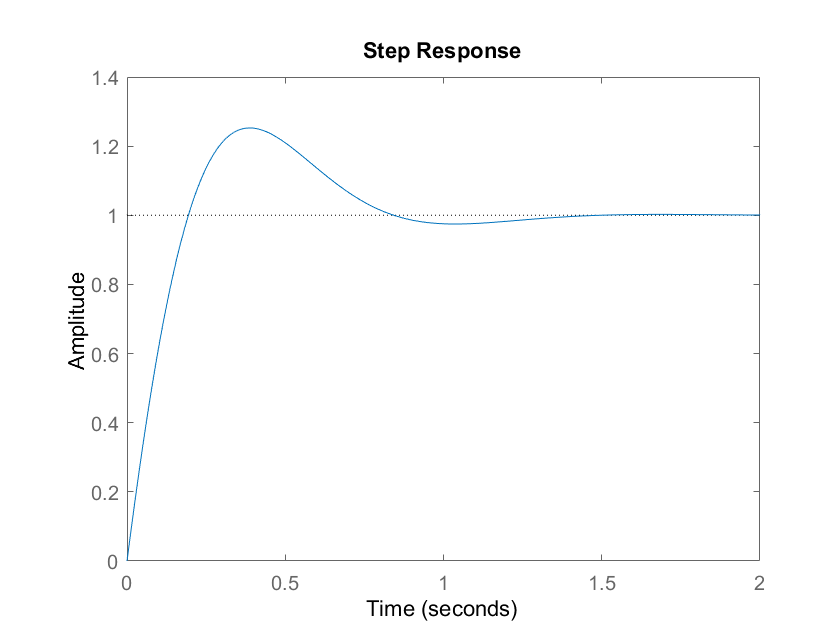

step(CL_inner)

isstable(CL_inner)

ans = logical
   1


The this first controller meets the rise time specifications but not the overshoot or settling time. The choice to use two real poles instead of a complex pair was taken to minimize overshoot and have a behavior similar to a first order system. With this being the case, the PID gains can be written in the following form:

- 
$$K_p =\frac{123}{2500}\left(\textrm{ab}\right)$$


- 
$$K_d =\frac{-123}{2500}\left(a+b\right)$$


where $\left\lbrace a,b\left|\left(s-a\right)\left(s-b\right)=0,s\in \Re^- \right.\right\rbrace$

Using equations available in the Systems Dynamics textbook, a choice of a and b were taken to achieve the desired behavior. The final design goes as follows.

a = -0.25;
b = -15;

Kp_roll = (a*b)/(2500/123);
Kd_roll = (-a-b)/(2500/123);
C_inner = tf([Kd_roll,Kp_roll,0],[1,0])

C_inner =
 
  0.7503 s^2 + 0.1845 s
  ---------------------
            s
 
Continuous-time transfer function.



CL_inner = minreal(feedback(C_inner*G_ThetaTau,1))

CL_inner =
 
     15.25 s + 3.75
  --------------------
  s^2 + 15.25 s + 3.75
 
Continuous-time transfer function.



stepinfo(CL_inner)

ans = struct with fields:
        RiseTime: 0.1376
    SettlingTime: 0.2227
     SettlingMin: 0.9048
     SettlingMax: 1.0145
       Overshoot: 1.4507
      Undershoot: 0
            Peak: 1.0145
        PeakTime: 0.5557


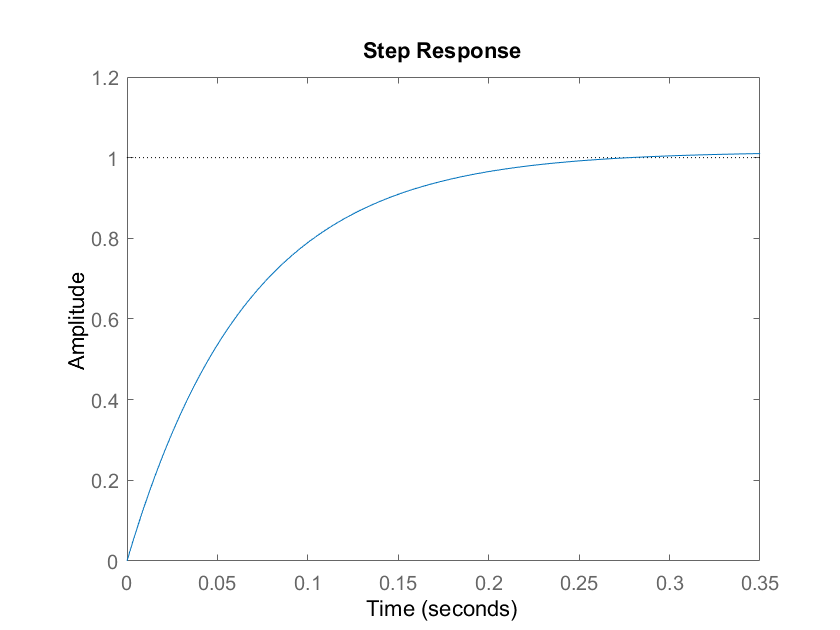

step(CL_inner)

isstable(CL_inner)

ans = logical
   1


### 1.9.2 - Outer Loop Controller Design (Pole Placement)

The outer loop controller (lateral position controller) has the following time domian specifications:

- $T_r \approx 3\left\lbrack s\right\rbrack$- asked for in the project

- $T_s \le 8\;\left\lbrack s\right\rbrack$ - asked for in the project

- $M_% \le 10\;%$- minimize oscillations when following trajectory

These constraints can be converted to possible pole regions by the follwing equations:

- 
$$\omega_n \approx \frac{1\ldotp 8}{T_r }$$


- 
$$\zeta \approx \frac{4}{T_s \omega_n }$$


From the the fact that transfer function $G_{\Theta T} \left(0\right)G_{Z\Theta } \left(s\right)$ is a second order system with a pole at $s=0$, PD controller should be sufficient to meet the criteria

syms K_p K_d K_i
Cp1 = K_p + K_d*s;
CL3 = collect(simplify((dcgain(CL_inner)*G_ZTheta*Cp1)/(1 + dcgain(CL_inner)*G_ZTheta*Cp1)),s)

$$CL3 = \frac{\left(2943\,K_{d}\right)\,s+2943\,K_{p}}{-300\,s^{2}+\left(2943\,K_{d}-20\right)\,s+2943\,K_{p}}$$

[Num,Den] = numden(G_ZTheta);
G_ZTheta = tf(dcgain(CL_inner)*sym2poly(Num),sym2poly(Den));

From the closed loop transfer function and the Routh–Hurwitz stability criteria, bounds on the values of $K_p$ and $K_d$can be found.

- 
$$\omega_n^2 <0\to K_p <0$$


- 
$$2\zeta \omega_n <0\to K_d <\frac{20}{2943}$$


t_r = 3;
t_s = 8;

omega_n = 1.8/t_r;
zeta = 4/(t_s*omega_n);

Kp_pos = (-300/2943)*(omega_n)^2;
Kd_pos = (-600*zeta*omega_n +20)/2943;
C_outer = tf([Kd_pos,Kp_pos,0],[1,0])

C_outer =
 
  -0.09514 s^2 - 0.0367 s
  -----------------------
             s
 
Continuous-time transfer function.



CL_outer = minreal(feedback(C_outer*G_ZTheta,1))

CL_outer =
 
  0.9333 s + 0.36
  ---------------
  s^2 + s + 0.36
 
Continuous-time transfer function.



stepinfo(CL_outer)

ans = struct with fields:
        RiseTime: 1.4560
    SettlingTime: 8.4605
     SettlingMin: 0.9259
     SettlingMax: 1.1404
       Overshoot: 14.0441
      Undershoot: 0
            Peak: 1.1404
        PeakTime: 3.7762


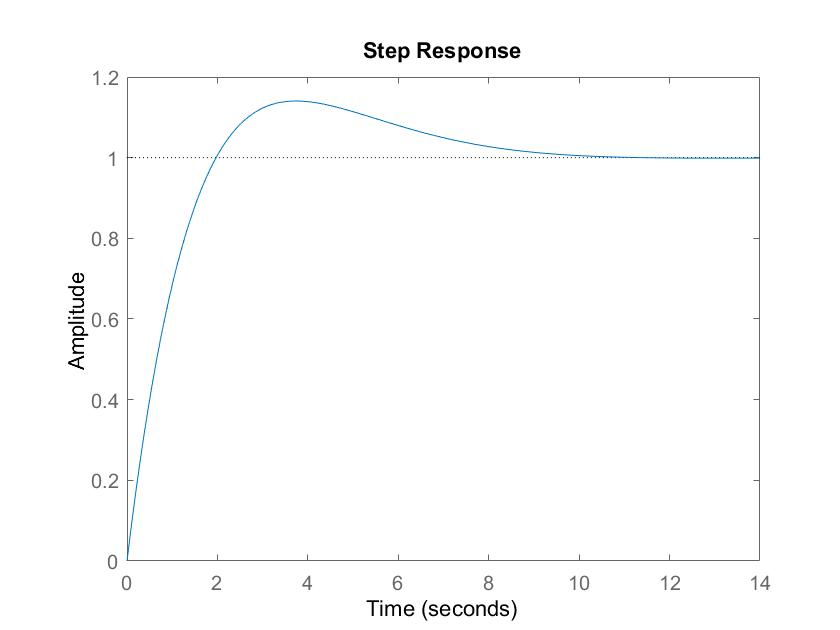

step(CL_outer)

isstable(CL_outer)

ans = logical
   1


Although the system is stable and has relatively good performance, it does not meet the system requirements. The rise time is too small, the settling time is too large and the overshoot is too high. This means that redesign of the controller has to be done. It was choosen to find two negative real poles for the system to meet the criteria.

omega_n = 0.2;
zeta = 2;

Kp_pos = (-300/2943)*(omega_n)^2;
Kd_pos = (-600*zeta*omega_n +20)/2943;
C_outer = tf([Kd_pos,Kp_pos,0],[1,0])

C_outer =
 
  -0.07475 s^2 - 0.004077 s
  -------------------------
              s
 
Continuous-time transfer function.



CL_outer = minreal(feedback(C_outer*G_ZTheta,1))

CL_outer =
 
   0.7333 s + 0.04
  ------------------
  s^2 + 0.8 s + 0.04
 
Continuous-time transfer function.



stepinfo(CL_outer)

ans = struct with fields:
        RiseTime: 3.1463
    SettlingTime: 6.6624
     SettlingMin: 0.9026
     SettlingMax: 0.9925
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9925
        PeakTime: 17.2136


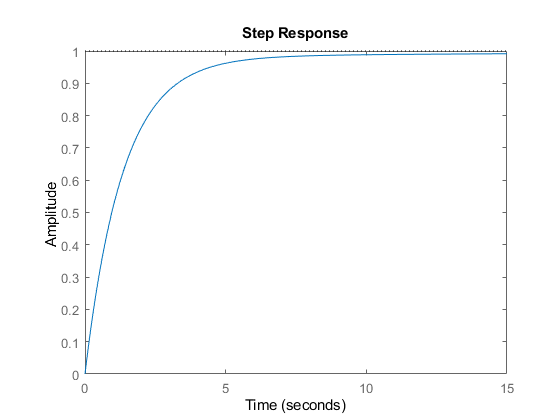

step(CL_outer)

isstable(CL_outer)

ans = logical
   1


### 1.10 - Linearized Simulation

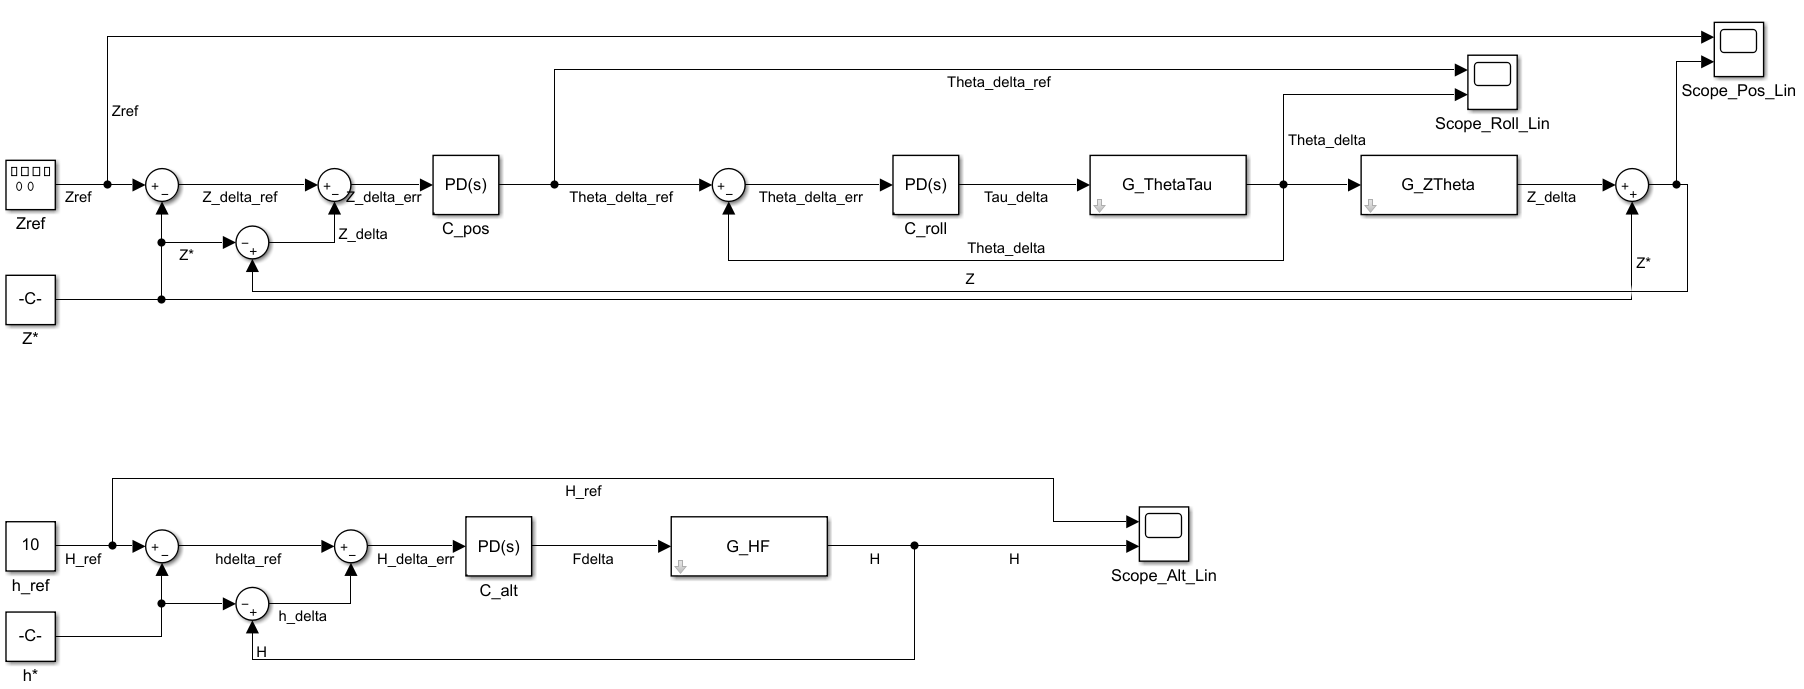

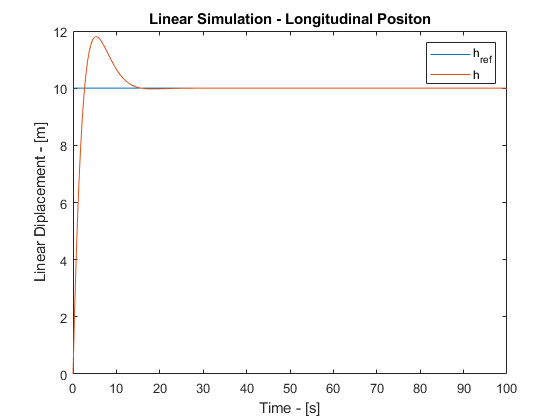

LS1 = sim('Part1_linsim',100);
plot(LS1.Alt.time,LS1.Alt.signals(1).values)
hold on
plot(LS1.Alt.time,LS1.Alt.signals(2).values)
hold off
title("Linear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

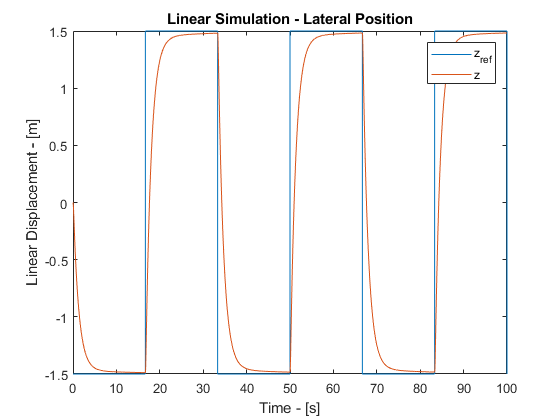

plot(LS1.Pos.time,LS1.Pos.signals(1).values)
hold on
plot(LS1.Pos.time,LS1.Pos.signals(2).values)
hold off
title("Linear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.11 - Nonlinear Simulation

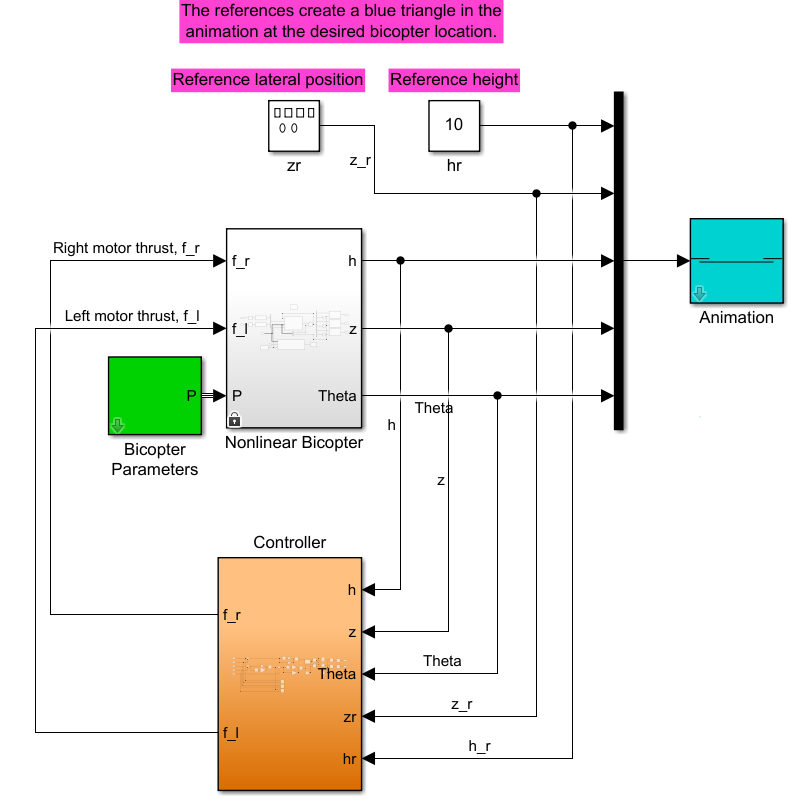

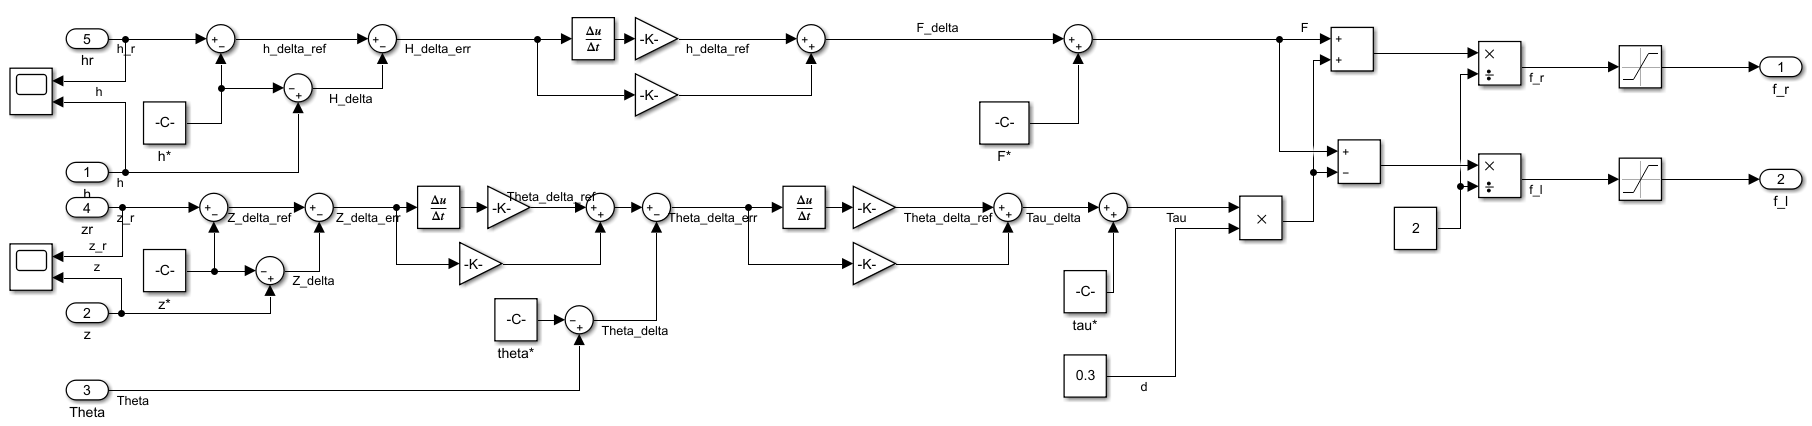

wind = 0;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

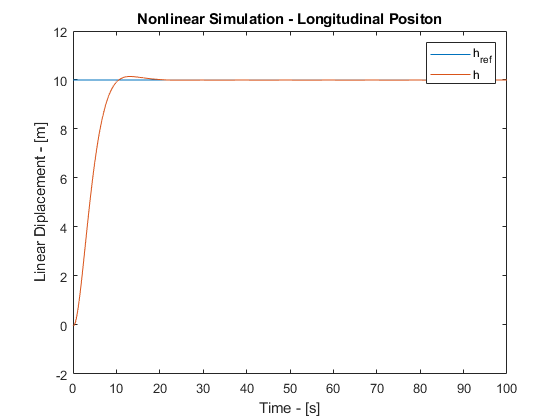

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

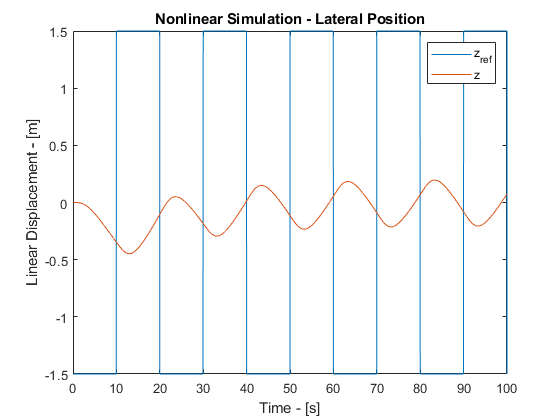

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

As it can be seen above, the linear controllers in the nonlinear model does not track the lateral position properly. The lateral controllers were returned to better track the trajectories.

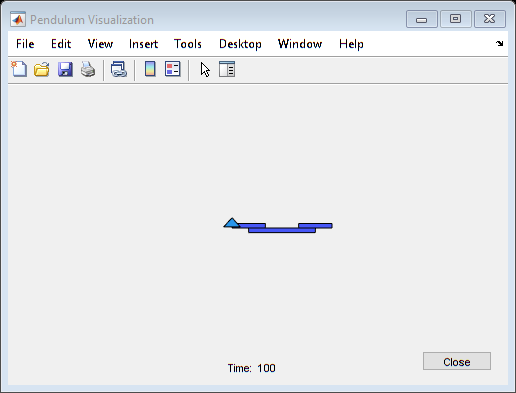

Kp_roll = 10;
Kd_roll = 10;

Kp_pos = -2.5;
Kd_pos = -1.25; 

wind = 0;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

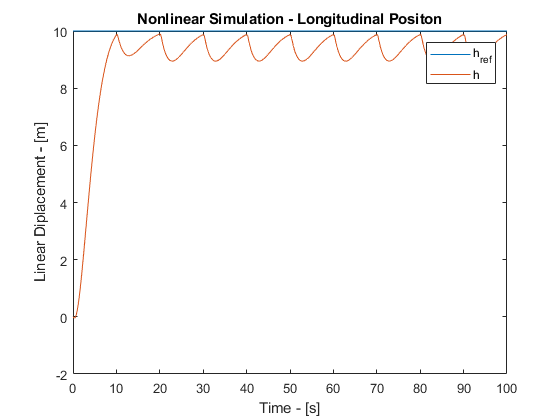

NLS1_orig = NLS1;
plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

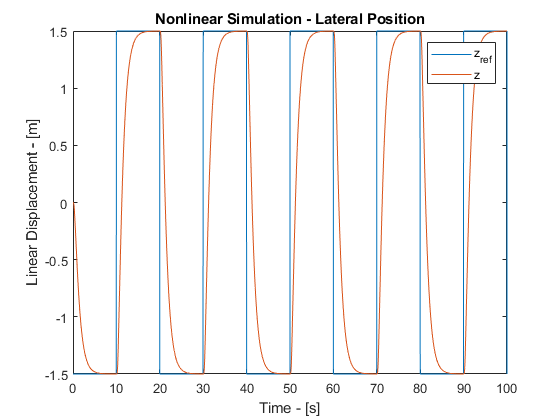

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.12 - Simulation Comparison

The controllers in the linear simulation are able to track the reference trajectories with some overshoot. The same controllers when implemented in the nonlinear simulation do not track the lateral reference properly. This was expected because the controller was designed for a linearized system. The controllers had to be modified to track the lateral trajectory properly. After this modification, the system was able to track the reference trajectories properly.

### 1.13 - Addition of Noise 

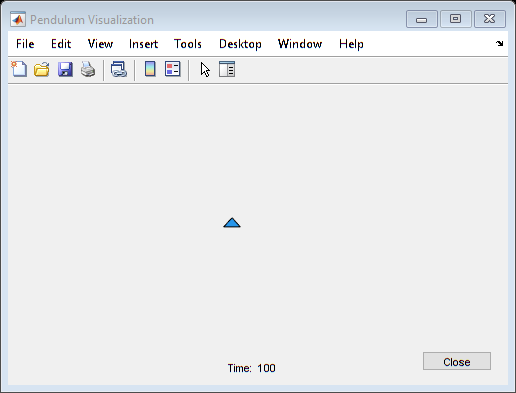

wind = 0;
variaciones = 0;
noise = 1e-6;
NLS1 = sim('Part1_planarBicopter');

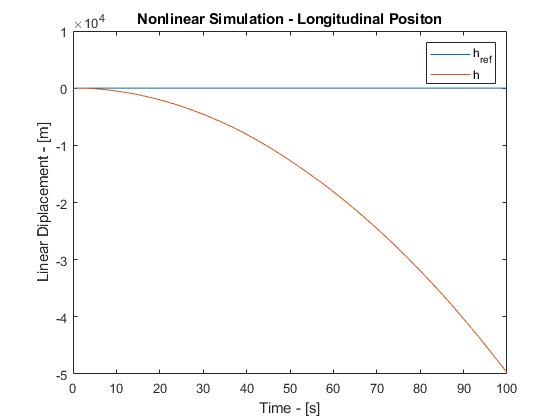

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

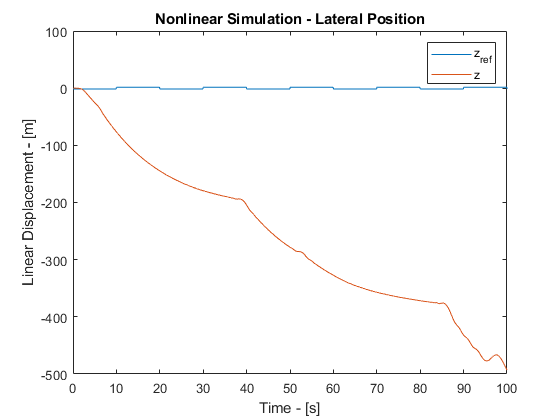

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

As the graphs above show, the controllers are not robust to noise in measurements and becomes highly unstable.

### 1.14 - Parameter Variations

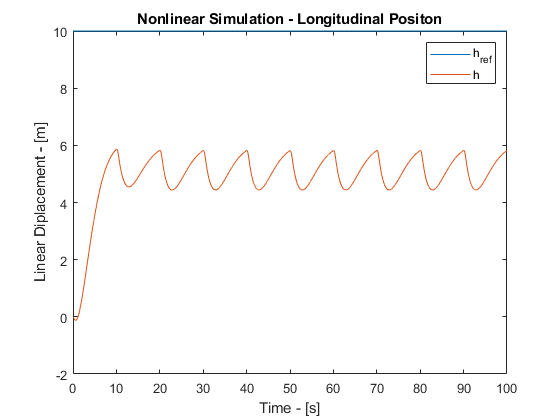

wind = 0;
variaciones = 20;
noise = 0;
NLS1 = sim('Part1_planarBicopter');
plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

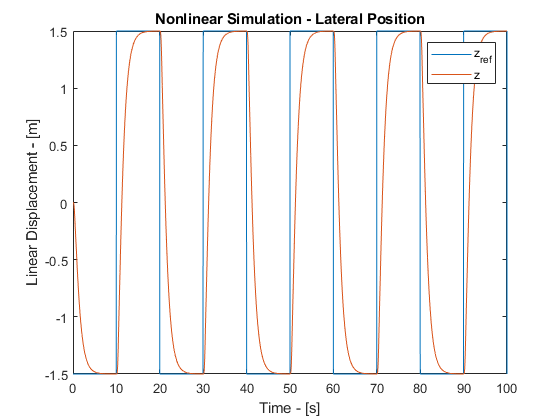

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

As the graphs above show, the controller is not robust against parameter variations. It does not reach the $10\;\left\lbrack m\right\rbrack$ and falls significantly when tracking the lateral position. This means that the controllers need to be retuned, in particular the altitude controller. The retuning was done to make it more aggresive in its response without overshooting and oscillating.

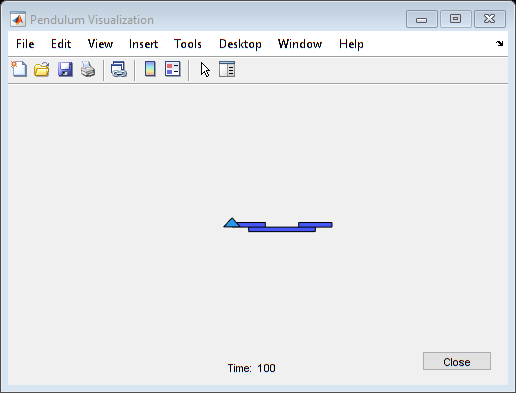

Kp_alt = 50;
Kd_alt = 100;

wind = 0;
variaciones = 20;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

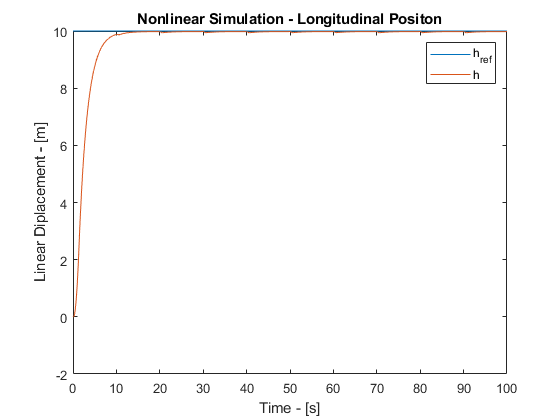

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

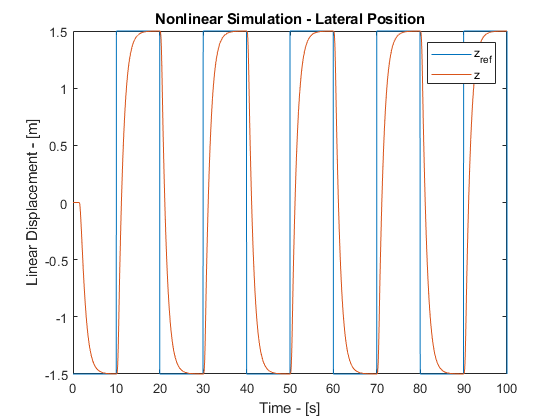

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.15 - Addition of Wind

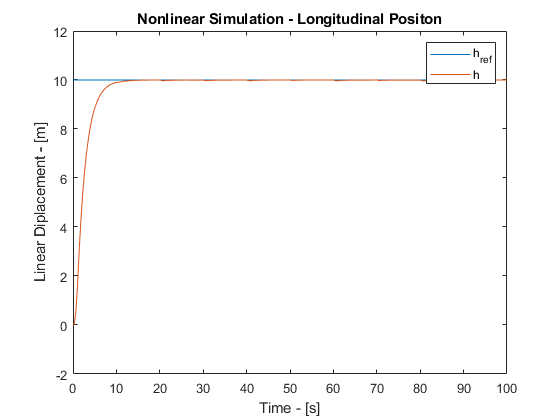

wind = 1;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');
plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

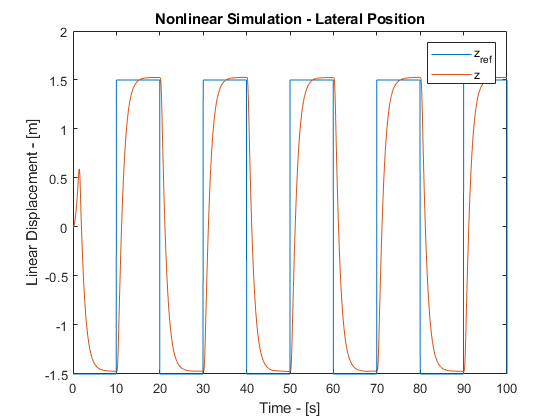

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

Under wind distrubances, the controller does not reach a zero steady-state error. The position controller has to be retuned to make it more agressive in the outer loop.

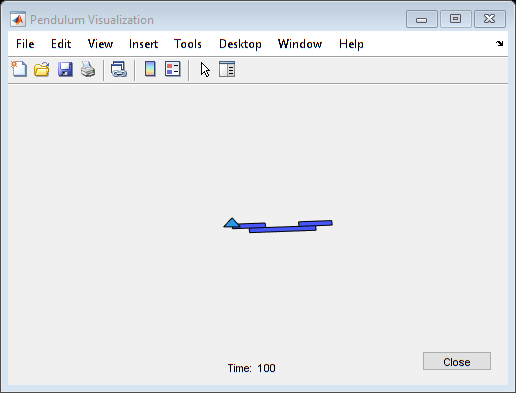

Kp_pos = -3;
Kd_pos = -2;

wind = 1;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

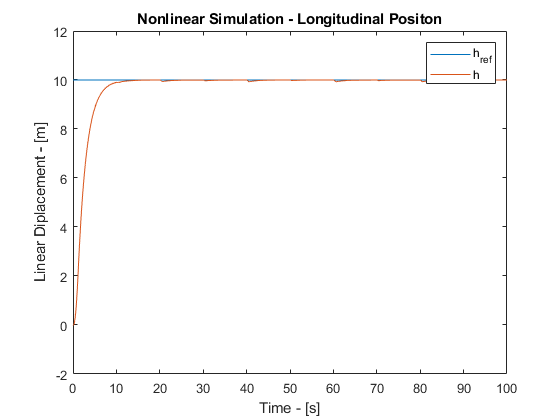

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

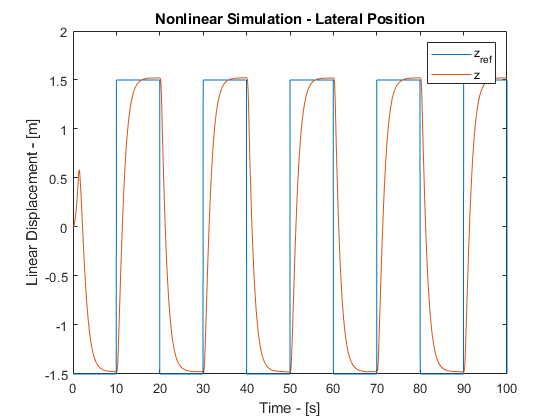

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

## Part 2

### 2.1 - Longitudinal (Loop Shaping)

Design a controller that generates linearized thrust commands and satisfies the following constraints:

- 
$$\omega_B \le 2\;\frac{\textrm{rad}}{s}$$


- 
$$\epsilon_w \ge 0\ldotp 1\;\forall \;\omega_w \le 0\ldotp 01\;\frac{\textrm{rad}}{s}\;$$


- 
$$\epsilon_{\textrm{no}} \le 0\ldotp 0005\;\forall \;\omega_{\textrm{no}} \ge 100\;\frac{\textrm{rad}}{s}$$


- 
$$\textrm{PM}\ge \frac{\pi }{3}\;\textrm{rad}$$


omega_w = 0.01;
mag_w = 20*log10(1/0.1);
omega_no = 100;
mag_no = 20*log10(0.0005);
w = [omega_w omega_no];

The first step is to see what the Bode plot for the open loop looks like to know what type of compensators to implement.

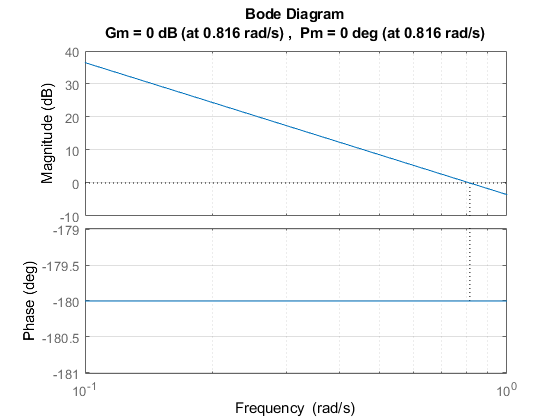

C_alt2 = 1;
margin(C_alt2*G_HF),grid

Since the bode plot does not have any phase, the first step would be adding a lead compensator.

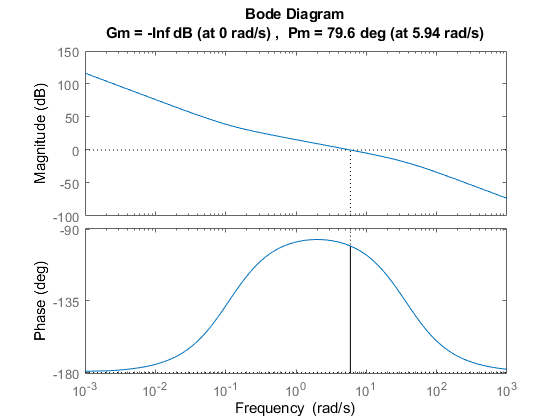

phi_lead = -80;
omega_lead = 2;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
CLead = tf([M, omega_lead*sqrt(M)],[1, omega_lead*sqrt(M)]);
C_alt2 = C_alt2 * CLead;
margin(C_alt2*G_HF),

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

After adding the lead compensator, the bode plot meets the distrubances and phase margin requirements. Next step is adding a low pass filter to meet the noise requirements.

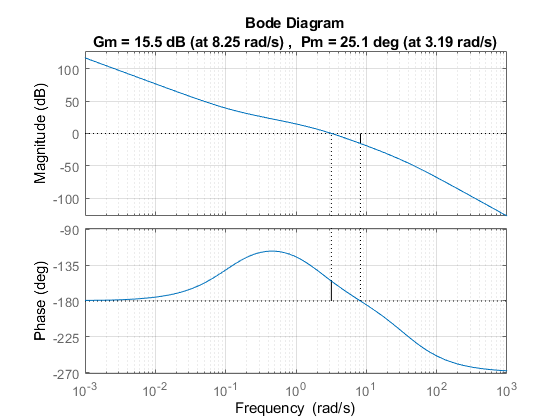

LPF = tf([2],[1,2]);
C_alt2 = C_alt2 * LPF;
margin(C_alt2*G_HF),grid;

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


The last step is adding a proportional controller to lower bandwidth and increase the phase margin back to meet the requirements.

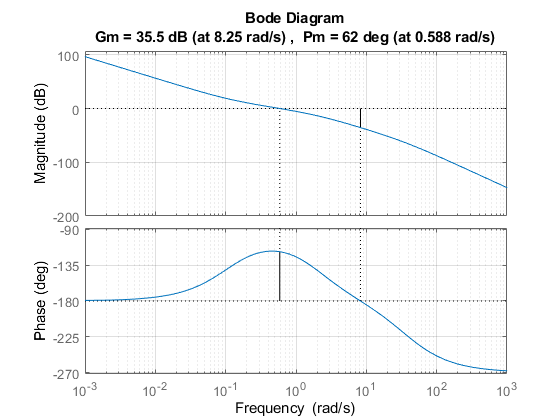

P = 0.1;
C_alt2 = C_alt2 * P;
margin(C_alt2*G_HF),grid

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


With all the requirements met, it's time to test the closed loop transfer function for stability and with a step response.

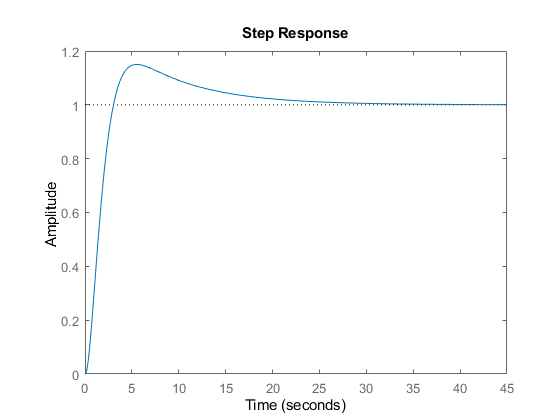

CL_alt2 = minreal(feedback(C_alt2*G_HF,1));
step(CL_alt2)

stepinfo(CL_alt2)

ans = struct with fields:
        RiseTime: 2.0555
    SettlingTime: 20.6869
     SettlingMin: 0.9056
     SettlingMax: 1.1499
       Overshoot: 14.9942
      Undershoot: 0
            Peak: 1.1499
        PeakTime: 5.5059


isstable(CL_alt2)

ans = logical
   1


### 2.2.1 - Inner Loop

Design an inner loop controller that satisfies the following constraints:

- 
$$\omega_B \ge 10\;\frac{\textrm{rad}}{s}$$


- 
$$\epsilon_{\textrm{no}} \le 0\ldotp 0001\;\forall \;\omega_{\textrm{no}} \ge 1000\;\frac{\textrm{rad}}{s}$$


- 
$$\textrm{PM}\ge \frac{\pi }{3}\;\textrm{rad}$$


omega_no = 1000;
mag_no = 20*log10(0.0001);
w = [omega_no];

First step is knowing what open loop transfer function looks like to determine what are appropiate compensators.

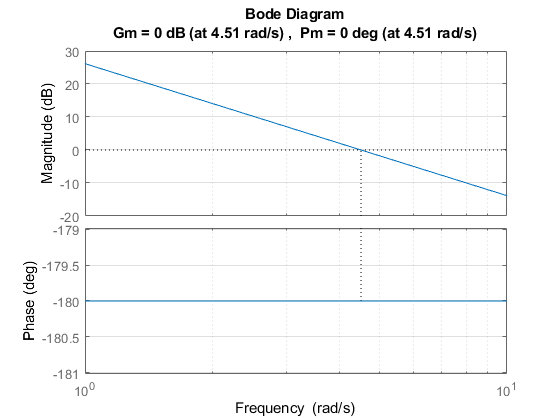

C_roll2 = 1;
margin(C_roll2*G_ThetaTau),grid

The controller needs to have phase added to the meet the phase margin constraints.

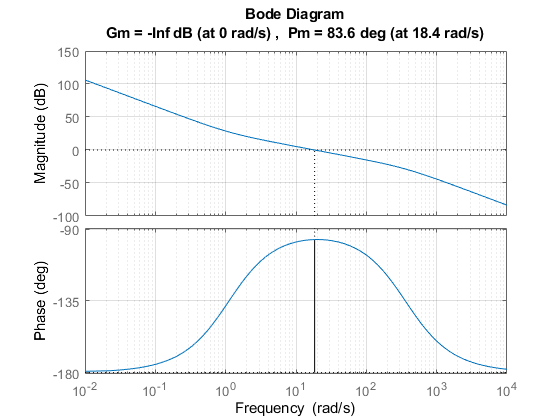

phi_lead = -80;
omega_p = 20;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_roll2 = C_roll2 * C_lead;
margin(C_roll2*G_ThetaTau),grid

[mag, phase, wout]=bode(C_roll2*G_ThetaTau,w);
if 20*log10(mag) < mag_no
    disp("Noise met")
end

After adding the phase, a second order butterworth filter with $\omega_c =1$00

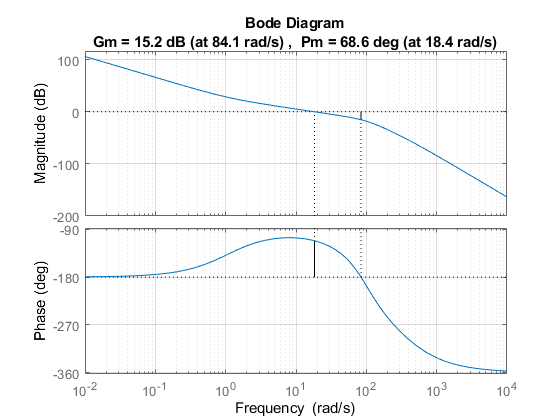

omega_c = 100;
LPF = tf([omega_c^2],[1, sqrt(2)*omega_c, omega_c^2]);
C_roll2 = C_roll2 * LPF;
margin(C_roll2*G_ThetaTau),grid

[mag, phase, wout]=bode(C_roll2*G_ThetaTau,w);
if 20*log10(mag) < mag_no
    disp("Noise met")
end

Noise met


With the butterworh filter, all of the requirements are met. Now the closed-loop can be simulated.

CL_roll2 = minreal(feedback(C_roll2*G_HF,1))

CL_roll2 =
 
                          2.175e06 s + 2.408e06
  ---------------------------------------------------------------------
  s^5 + 502.7 s^4 + 6.109e04 s^3 + 3.613e06 s^2 + 2.175e06 s + 2.408e06
 
Continuous-time transfer function.



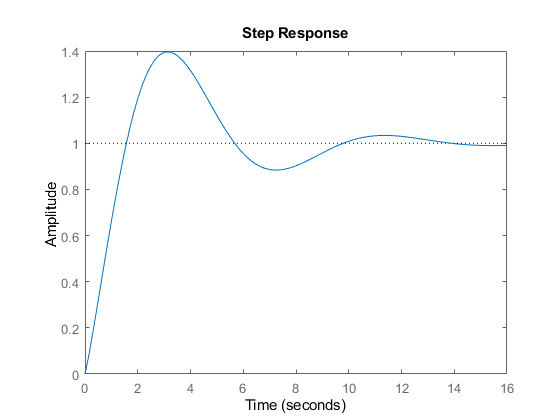

step(CL_roll2)

stepinfo(CL_roll2)

ans = struct with fields:
        RiseTime: 1.2100
    SettlingTime: 12.6661
     SettlingMin: 0.8837
     SettlingMax: 1.3960
       Overshoot: 39.5985
      Undershoot: 0
            Peak: 1.3960
        PeakTime: 3.0865


isstable(CL_roll2)

ans = logical
   1


The controller has a settling time and overshoot much larger than desired but we will carry on and see how the rest of the system behaves.

### 2.2.2 - Outer Loop

Design an outer loop controller that satisfies the following constraints:

- 
$$\omega_B \le 1\;\frac{\textrm{rad}}{s}$$


- 
$$\epsilon_w \ge 0\ldotp 1\;\forall \;\omega_w \le 0\ldotp 001\frac{\textrm{rad}}{s}\;$$


- 
$$\epsilon_{\textrm{no}} \le 0\ldotp 0001\;\forall \;\omega_{\textrm{no}} \ge 100\;\frac{\textrm{rad}}{s}$$


- 
$$\textrm{PM}\ge \frac{\pi }{4}\;\textrm{rad}$$


omega_w = 0.01;
mag_w = 20*log10(1/0.1);
omega_no = 100;
mag_no = 20*log10(0.0001);
w = [omega_w omega_no];

Start by plotting the bode plot of the transfer function with a gain of negative one, which is needed to make the transfer function BIBO stable.

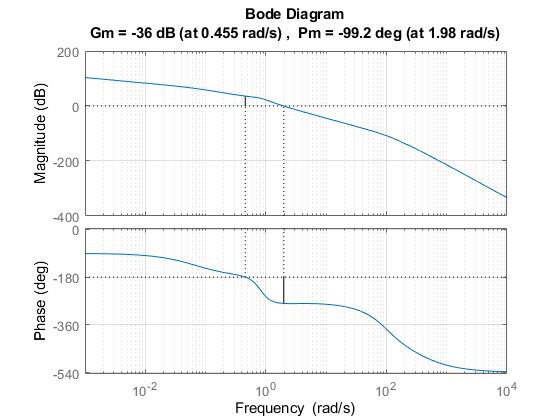

C_pos2 = -1;
margin(C_pos2*CL_roll2*G_ZTheta),grid

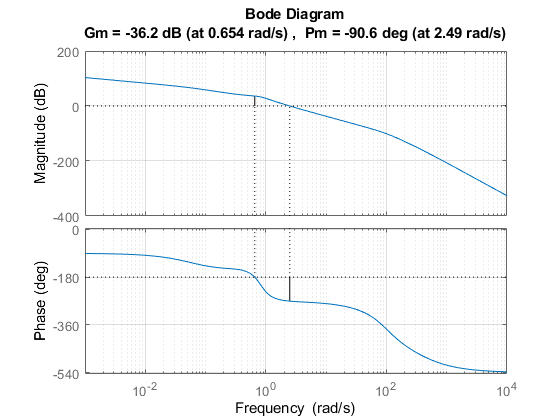

phi_lead = -75;
omega_p = 0.5;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_pos2 = C_pos2 * C_lead;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


Add phase to the system to meet the phase criteria after the next step

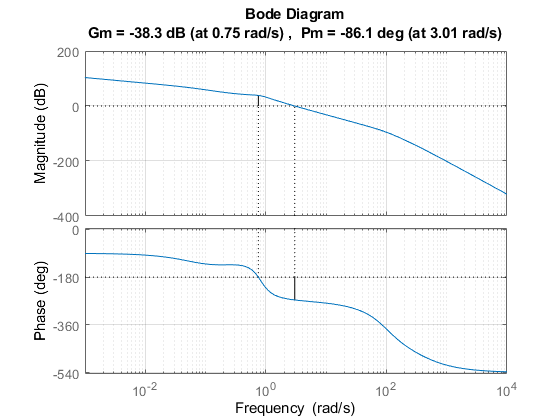

phi_lead = -60;
omega_p = 0.5;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_pos2 = C_pos2 * C_lead;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


Lower the bandwith and increase the phase margin to meet design criteria

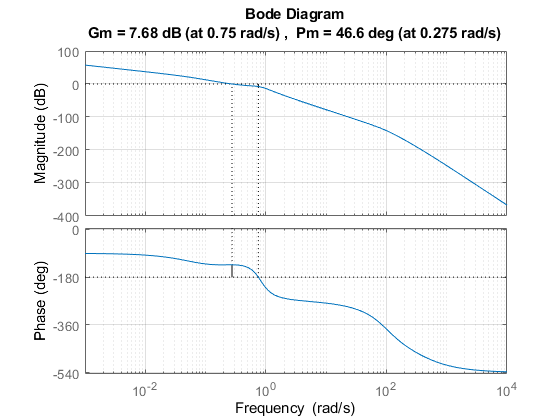

P = 0.005;
C_pos2 = C_pos2 * P;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


With all the requirements met, the closed loop can be simulated

CL_pos2 = minreal(feedback(C_pos2*CL_roll2*G_ZTheta,1))

CL_pos2 =
 
                                         4.539e05 s^3 + 8.19e05 s^2 + 4.054e05 s + 6.092e04
  ---------------------------------------------------------------------------------------------------------------------------------
  s^9 + 504.2 s^8 + 6.185e04 s^7 + 3.705e06 s^6 + 7.647e06 s^5 + 7.892e06 s^4 + 5.531e06 s^3 + 2.367e06 s^2 + 4.881e05 s + 6.092e04
 
Continuous-time transfer function.



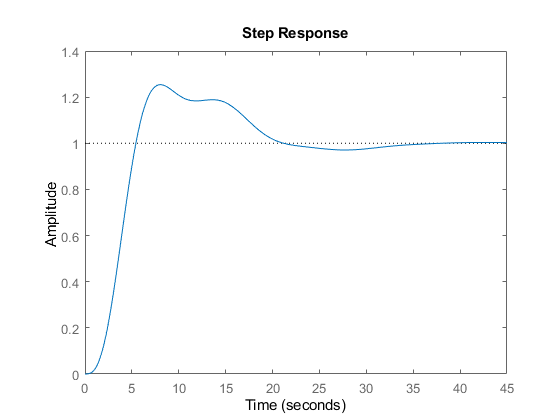

step(CL_pos2)

stepinfo(CL_pos2)

ans = struct with fields:
        RiseTime: 3.1614
    SettlingTime: 30.8954
     SettlingMin: 0.9022
     SettlingMax: 1.2541
       Overshoot: 25.4147
      Undershoot: 0
            Peak: 1.2541
        PeakTime: 8.0071


isstable(CL_pos2)

ans = logical
   1


Although the system is stable it is a high order system, has a fairly high settling time, and overshoot. It is very likely that the compensators do not work although it meets all design criteria.

### 2.3 - Linear Simulation

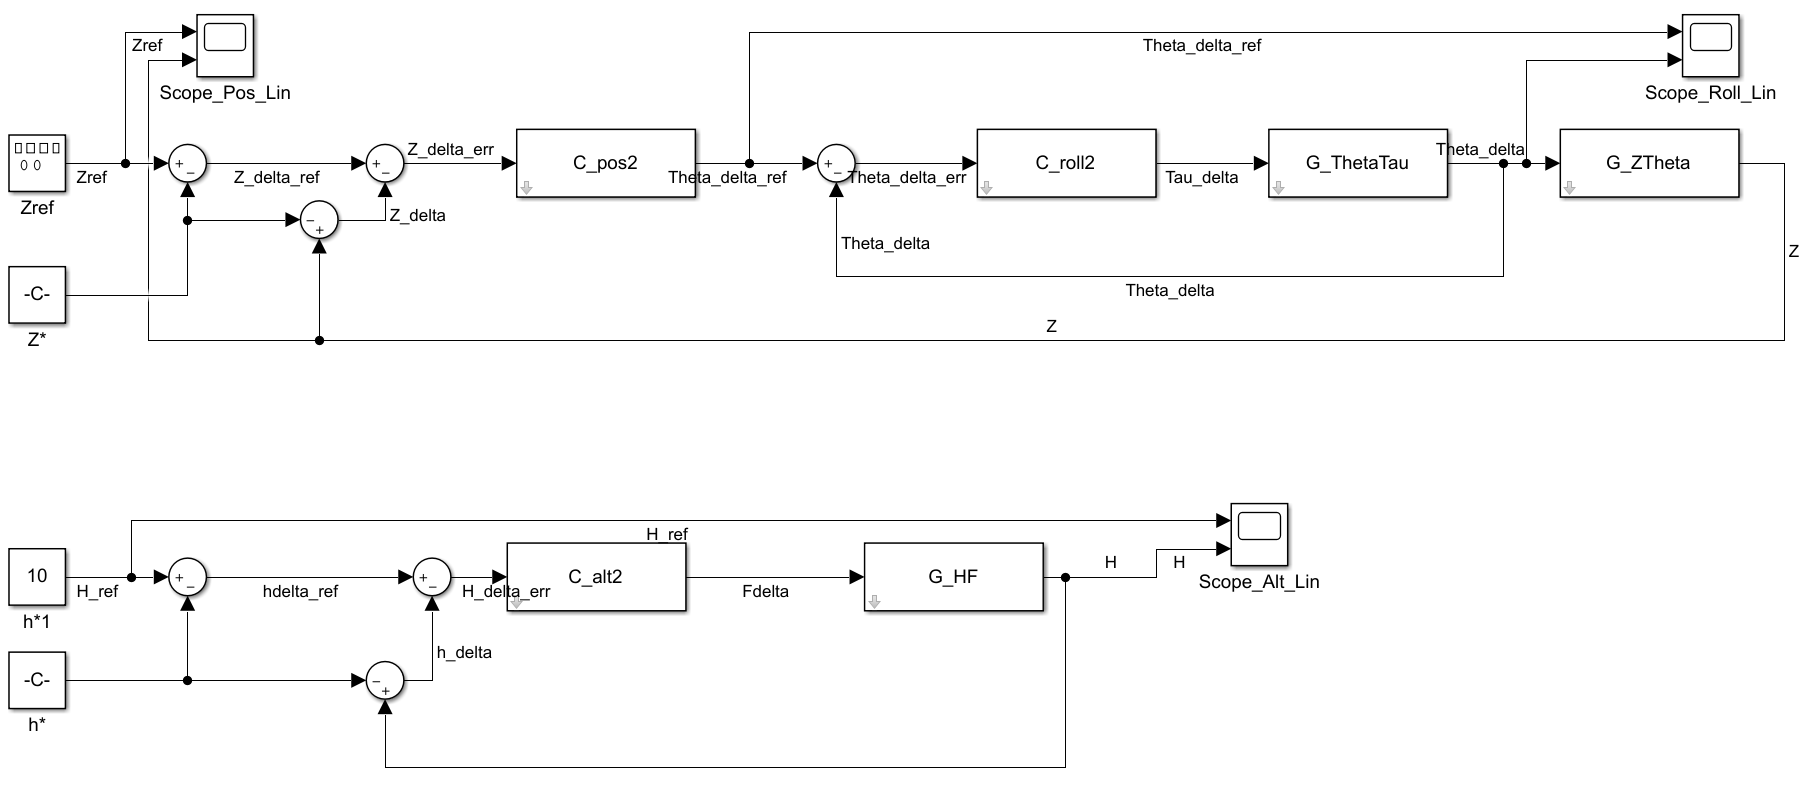

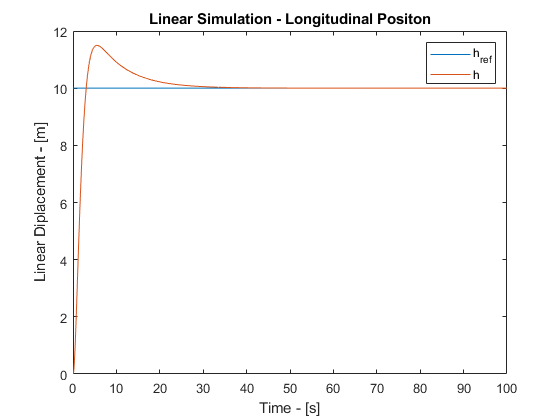

LS2 = sim('Part2_linsim',100);
plot(LS2.Alt.time,LS2.Alt.signals(1).values)
hold on
plot(LS2.Alt.time,LS2.Alt.signals(2).values)
hold off
title("Linear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

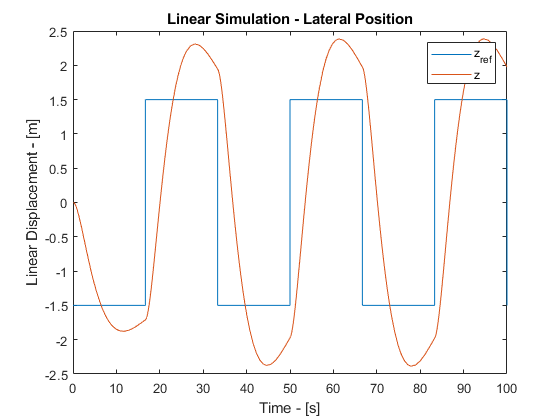

plot(LS2.Pos.time,LS2.Pos.signals(1).values)
hold on
plot(LS2.Pos.time,LS2.Pos.signals(2).values)
hold off
title("Linear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

The controller does not properly track the lateral position, this is due to the large settling times and overshoots present in the closed loop.

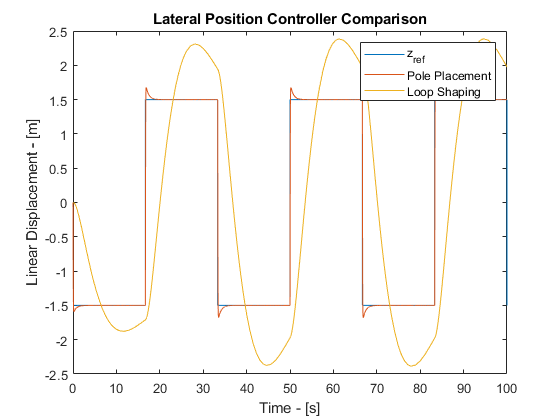

LS1 = sim('Part1_linsim',100);
LS2 = sim('Part2_linsim',100);
plot(LS1.Pos.time,LS1.Pos.signals(1).values)
hold on
plot(LS1.Pos.time,LS1.Pos.signals(2).values(:,:))
hold on
plot(LS2.Pos.time,LS2.Pos.signals(2).values(:,:))
hold off
title("Lateral Position Controller Comparison")
legend("z_{ref}","Pole Placement","Loop Shaping")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

 The pole placement method provided a better controller for trajectory tracking in the linearized model.

### 2.4 - Nonlinear Simulation

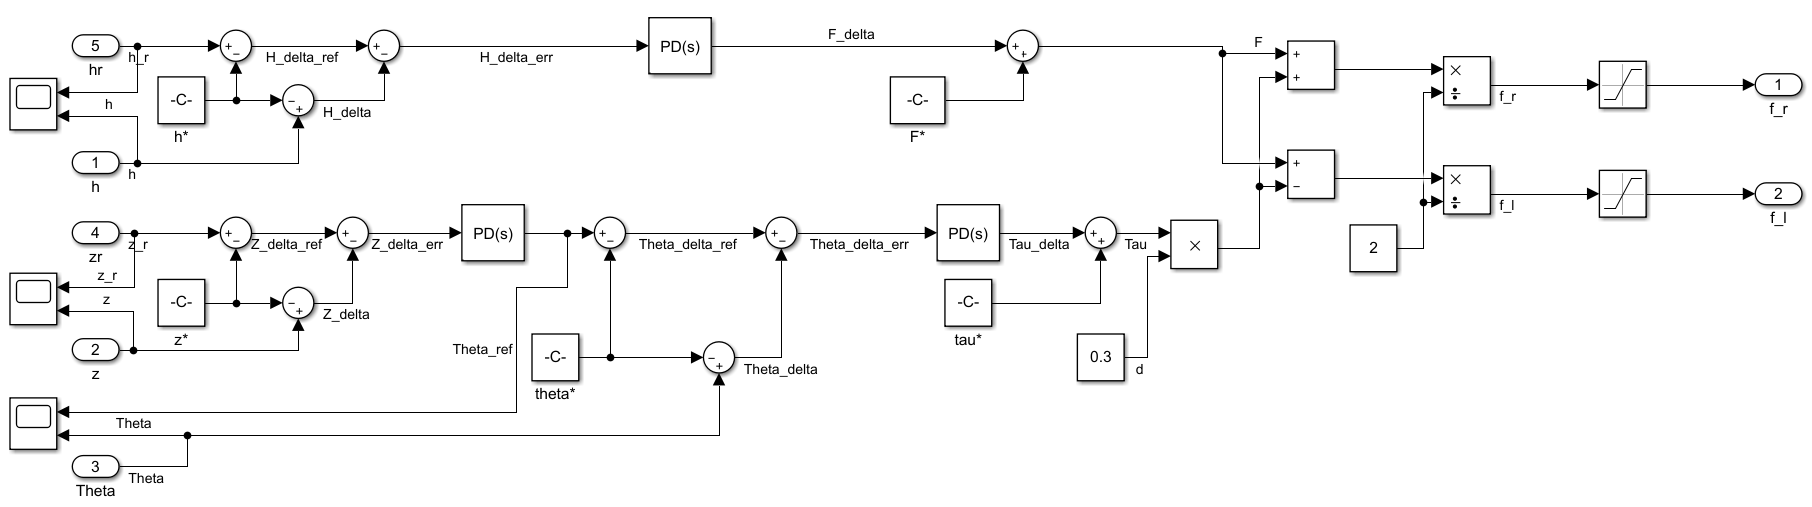

wind = 0;
variaciones = 0;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

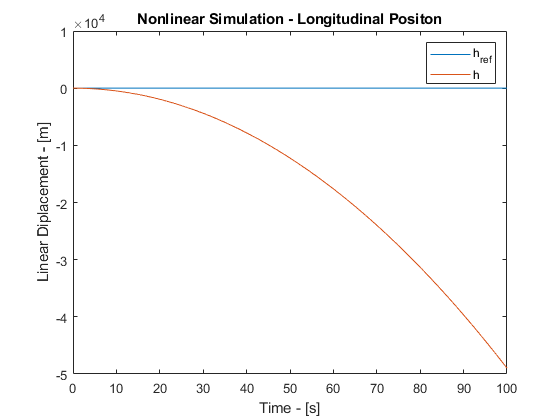

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

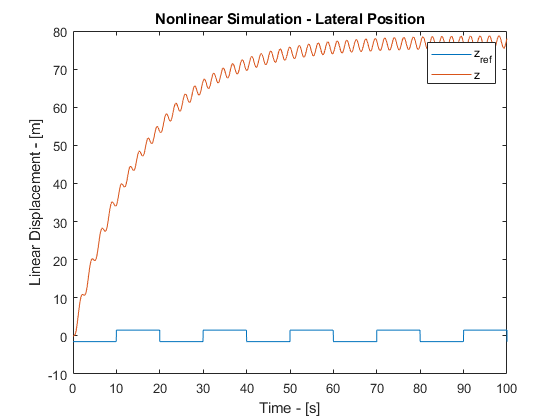

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

As it can be seen by the two graphs above, the loop shaping controllers do not perform properly with the nonlinear model. The controllers designed using pole placement performed better than those designed using loop shaping, yet for a fair comparisson both controllers should perform properly before comparing their efficacy.

### 2.6 Comparion between Linear and Nonlinear model

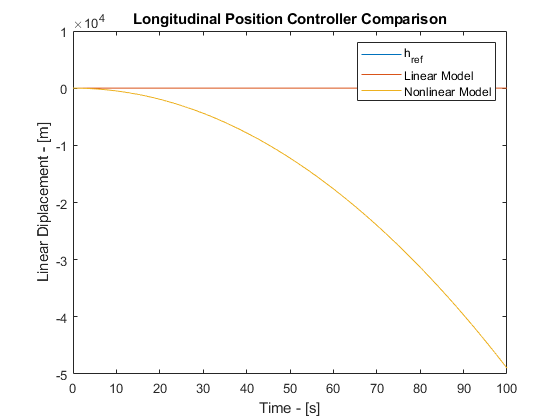

plot(LS2.Alt.time,LS2.Alt.signals(1).values)
hold on
plot(LS2.Alt.time,LS2.Alt.signals(2).values(:,:))
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Longitudinal Position Controller Comparison")
legend("h_{ref}","Linear Model","Nonlinear Model")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

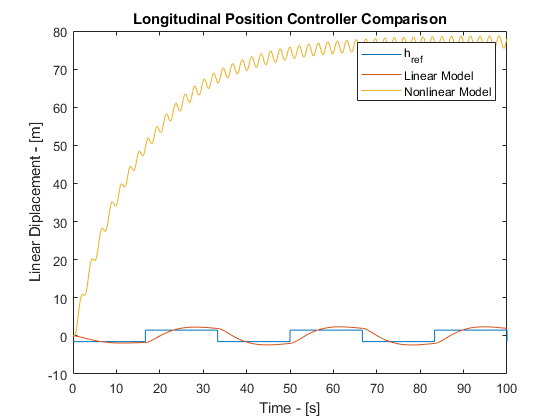

plot(LS2.Pos.time,LS2.Pos.signals(1).values)
hold on
plot(LS2.Pos.time,LS2.Pos.signals(2).values(:,:))
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Longitudinal Position Controller Comparison")
legend("h_{ref}","Linear Model","Nonlinear Model")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

Although the controllers in the linear simulation do not track the trajectories faithfully, they are much better than in the nonlinear simulation. This suggests that the nonlinearities present in the model can destabalize the model with any distrubances or noise added.

### 2.6 Addition of Noise

wind = 0;
variaciones = 0;
noise = 1e-6;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

Since neither of the two controllers were able to be stable and track the trajectory accurately, there is no proper comparison to make here. The controller with the best chance at properly handling the noise was the loop shaping controller, if it had worked properly.

### 2.7 Parameter Variation

wind = 0;
variaciones = 20;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

Given that the loop shaping controllers did not work as in the nonlinear model, there is no proper comparison to make here either. If an educated guess were to be made here based on how each method works, I would assume that the pole placement controllers would be best for controlling under parameter variations because small variations in the model parameters lead to small changes in  pole positions. Loop shaping does not take into account pole positioning when designing the controller, for this reason it makes most sense to me that the pole placement approach would provide the best results. 

### 2.8 Addition of Wind

wind = 1;
variaciones = 0;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

Similarly to section 2.8, there is no proper comparison to make here because the controllers designed using loop shaping did not work despite meeting all requirements. If an educated guess had to be made, I would assume that a functioning loop shaping controller would be best for distrubance rejection given the nature of the method.

### 2.9 Improvements

In order to achieve a functioning controller using loopshaping, I would modify the following criteria:

Longitudinal Control:

- None

Inner loop:

- Made the attenuation of the noise less to allow for a higher bandwidth without the need of higher order filters

-  to increase the speed at which it reacted to the position controller.

Outer loop:

- Increase the bandwidth for quicker response time